## Higher Order Dynamic Mode Decomposition

Lets assume a dynammic system given by the vector state variable **𝑣**(𝑡), of size 𝐽, we consider a set of 𝐾 snapshots at equispaced values of *t*

				
$$v_k \equiv v\left(t_k \right)\;$$


where $t_k =t_1 +\left(k-1\right)\ldotp \Delta t\;,\textrm{for}\;\textrm{𝑘}=1,\ldotp \ldotp \ldotp ,\textrm{𝐾}$

Assuming the dynamical system is infinite-dimensional, the finite- dimensional state vector V generally results from spatial discretization. The snapshots

are organized in a snapshot matrix (whose columns are the snapshots), as 

                            
$$V_1^k =\left\lbrack \upsilon_1 \;\;\;\;\upsilon_2 \;\;\;\ldotp \ldotp \ldotp \;\;\;\upsilon_k \right\rbrack$$


**Metrics: ** *relative root mean square *(RMS) error, defined as 

            
$$\textrm{error}=\sqrt{\frac{\sum_{k=1}^K {\left\|\;v_k^{\textrm{approx}} \;-v_k \right\|}_2^2 }{\sum_{k=1}^K {\left\|\;v_k \right\|}_2^2 }}$$


### Algorithm:

**SVD** : 

For dimensionality reduction, truncated SVD is applied to $V_1^k$, which yields,

                $V_1^k \approx P\Sigma Q^T$ $\equiv P\hat{{{\mathrm{T}}_1 }^K }$    (or $\upsilon_k$ $\equiv P\hat{t_k }$)

                            where $\hat{{\mathrm{T}}_1 }$ = $\Sigma Q^T$ 

where the matrix $\hat{{{\mathrm{T}}_1 }^K }$ is known as the dimension-reduced snapshot matrix and their columns, the *dimension-reduced snapshots*,$\hat{{\;t}_k }$.

**DMDd**: 	

For ordinary DMD, we consider the Koopman Assumption which can be formulated as,

                    
$${\hat{t} }_{k+1} ={\hat{R} }^{t\;} \ldotp {\hat{t} }_k$$


Where the M x M matrix ${\hat{R} }^{t\;}$is computed from dimension-reduced snapshots via pseudoinverse.

Reduced Snapshots can be represented by,

               
$$\hat{t_{k+d} } \approx \hat{R_1 } \hat{t_{k+d-1} } +\hat{R_2 } \hat{t_{k+d-2} \;} +\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +\hat{R_k } \hat{t_k \;} \;$$


The enlarged snapshots can be represented by,

                        
$$\widetilde{t_k } \equiv \left\lbrack \begin{array}{c}
\hat{t_k } \\
\hat{t_{k+1} } \\
\ldotp \ldotp \ldotp \\
\hat{t_{k+d-2} } \\
\hat{t_{k+d-1} } 
\end{array}\right\rbrack$$


SVD is applied to $\tilde{t_k }$ , a second dimension reduction that gives a new set of enlarges dimension-reduced snapshots, $\hat{\widetilde{t_k } }$ 

which will satisfy -  $\hat{\widetilde{t_{k+1} } } =\widetilde{R^t } \ldotp \hat{\widetilde{t_k } }$ , where $\tilde{R^t }$ is computed via the pseudo-inverse as defined above.

t = linspace(0,30,1000);
V = sqrt(1 + (1/2).*sin(t).*sin(sqrt(3)*t));
d = 800;
varepsilon1 = 10^-10;
varepsilon = 10^-4;
[Vreconst,~] =DMDd_SIADS(d,V,t,varepsilon1,varepsilon)

Vreconst =    1.0012 + 0.0000i   1.0020 + 0.0000i   1.0034 + 0.0000i   1.0057 + 0.0000i   1.0086 + 0.0000i   1.0123 + 0.0000i   1.0166 + 0.0000i   1.0216 + 0.0000i   1.0272 + 0.0000i   1.0333 + 0.0000i   1.0399 + 0.0000i   1.0469 + 0.0000i   1.0543 + 0.0000i   1.0620 + 0.0000i   1.0700 + 0.0000i   1.0781 + 0.0000i   1.0864 + 0.0000i   1.0948 + 0.0000i   1.1031 + 0.0000i   1.1114 + 0.0000i   1.1196 + 0.0000i   1.1277 + 0.0000i   1.1355 + 0.0000i   1.1430 + 0.0000i   1.1501 + 0.0000i   1.1569 + 0.0000i   1.1633 - 0.0000i   1.1692 - 0.0000i   1.1745 - 0.0000i   1.1793 - 0.0000i   1.1834 - 0.0000i   1.1870 - 0.0000i   1.1899 - 0.0000i   1.1921 - 0.0000i   1.1935 - 0.0000i   1.1943 - 0.0000i   1.1943 - 0.0000i   1.1936 + 0.0000i   1.1922 + 0.0000i   1.1900 + 0.0000i   1.1871 + 0.0000i   1.1835 + 0.0000i   1.1791 + 0.0000i   1.1741 + 0.0000i   1.1683 + 0.0000i   1.1619 + 0.0000i   1.1549 + 0.0000i   1.1472 + 0.0000i   1.1389 + 0.0000i   1.1300 + 0.0000i


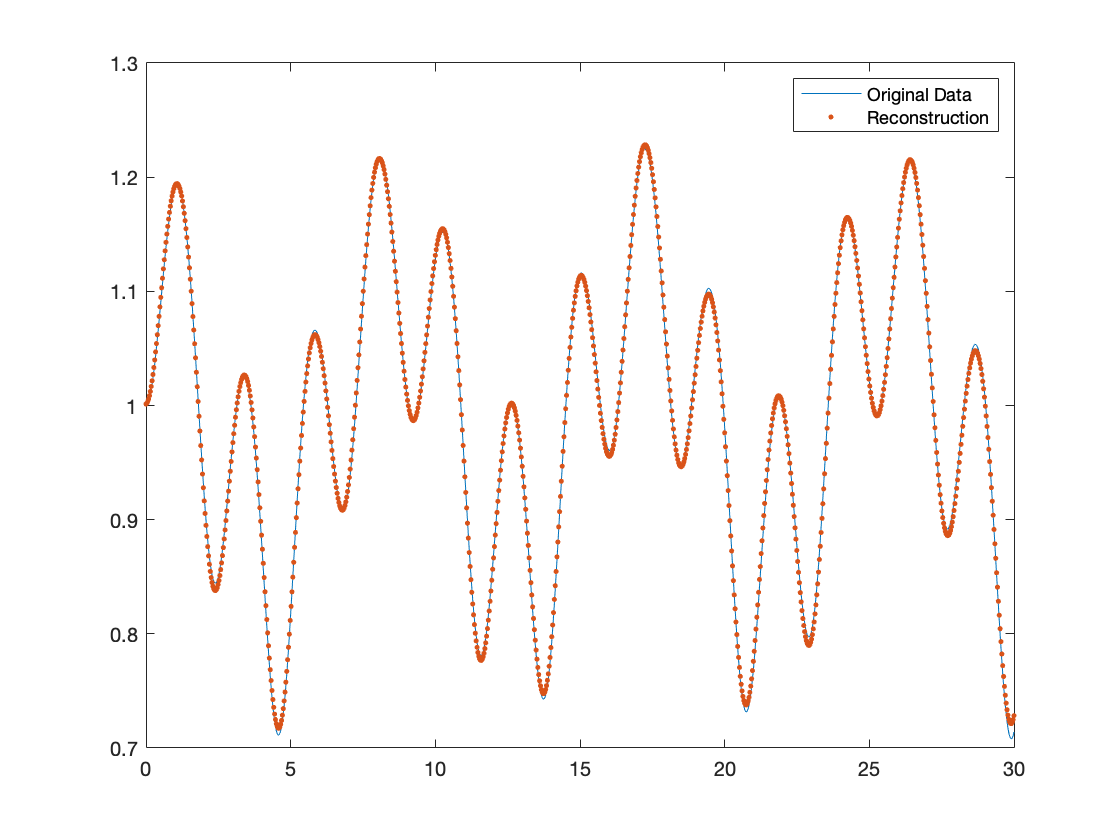

plot(t,V)
hold on
plot(t,real(Vreconst),'.')
legend("Original Data","Reconstruction")

t = linspace(0,100,length(Close));
d = 46;
varepsilon1 = 10^-10;
varepsilon = 10^-4;
[Vreconst,~] =DMDd_SIADS(d,Close',t,varepsilon1,varepsilon)

Vreconst = 	1.0e+04 *

   3.9266 + 0.0000i   3.8704 - 0.0000i   4.5549 - 0.0000i   4.6551 - 0.0000i   4.4727 - 0.0000i   4.7383 + 0.0000i   4.6991 - 0.0000i   4.7382 - 0.0000i   4.8784 - 0.0000i   4.7714 - 0.0000i   4.9798 - 0.0000i   5.2818 + 0.0000i   5.1521 - 0.0000i   5.5362 + 0.0000i   5.5480 - 0.0000i   5.6482 - 0.0000i   5.2617 + 0.0000i   4.7264 + 0.0000i   4.9156 + 0.0000i   4.7010 - 0.0000i   4.6186 - 0.0000i   4.7082 - 0.0000i   4.6753 + 0.0000i   5.1205 - 0.0000i   5.0342 + 0.0000i   5.2481 - 0.0000i   5.0025 - 0.0000i   4.9202 + 0.0000i   4.7419 - 0.0000i   4.9050 + 0.0000i   4.9526 - 0.0000i   5.2784 - 0.0000i   5.6597 - 0.0000i   5.8688 + 0.0000i   5.8325 - 0.0000i   6.0027 - 0.0000i   6.0474 - 0.0000i   5.8511 - 0.0000i   6.0482 + 0.0000i   6.0778 + 0.0000i   5.8752 - 0.0000i   5.9279 - 0.0000i   5.9216 + 0.0000i   5.7555 + 0.0000i   5.4083 - 0.0000i   5.4909 + 0.0000i   5.3186 + 0.0000i   5.1892 + 0.0000i   5.4200 + 0.0000i   5.4683 + 0.0000i


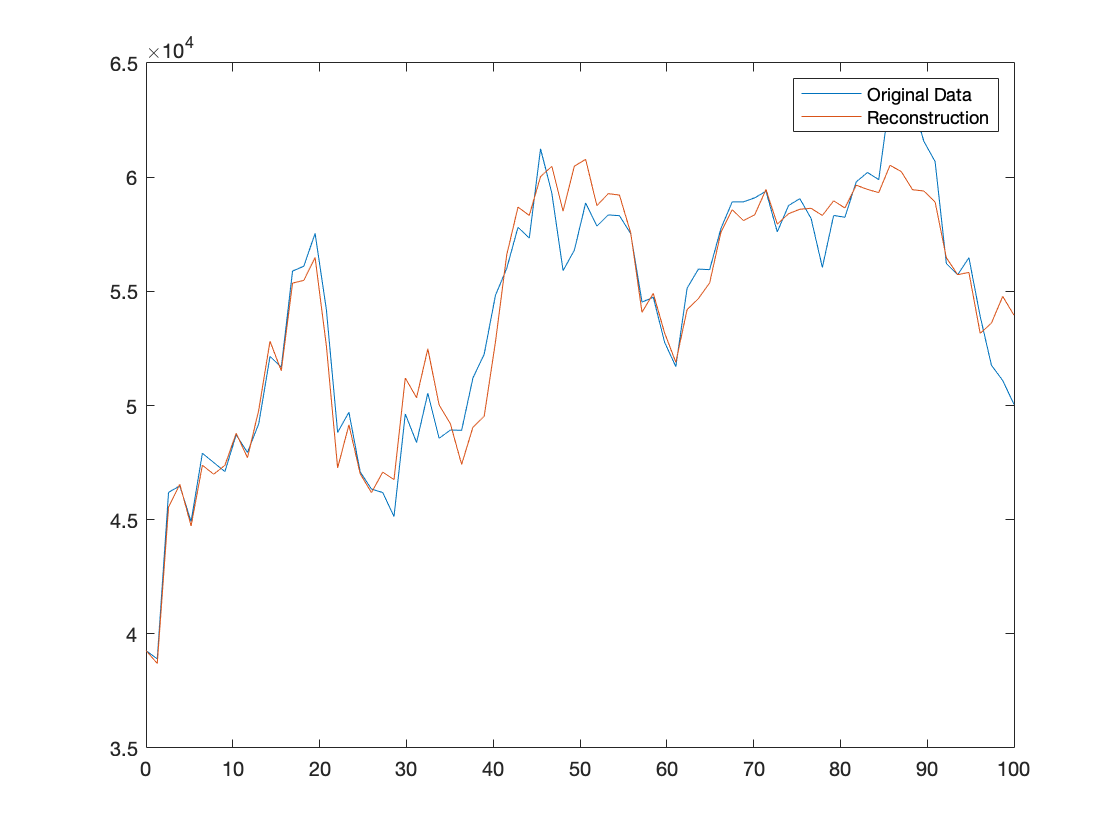

figure
plot(t,Close)
hold on
plot(t,real(Vreconst))
legend("Original Data","Reconstruction")

x = linspace(0,10,100);
t = linspace(0,100,100);
U = zeros(length(x));

varepsilon1 = 10^-8;
varepsilon2 = 10^-7;

for i=1:length(x)
    for j=1:length(t)
        X = x(i); T = t(j);
        U(i,j) = (0.5 + sin(X)) * (2*cos(2*X - (2*pi/45)*T) + 0.5*cos(10*X - sqrt(10)*T));
    end
end
figure



[Vreconst,Modes,Amplitudes,Amplitudesx,GrowthRatex,Frequencyx,Amplitudest,GrowthRatet,Frequencyt]=...
CalculateDMDdSdT(10,1,x,t,U,varepsilon1,varepsilon2);

Spatial Dimension: singular values
     4

Spatial dimension reduction
    12

size of a


ans =     12     1


size of Q


ans =      4    12


Spectral complexity
    12



ans = 'Spectral complexity'

kk3 = 4

    48

    12

Number of spatial modes
    12

Number of temporal modes
     4



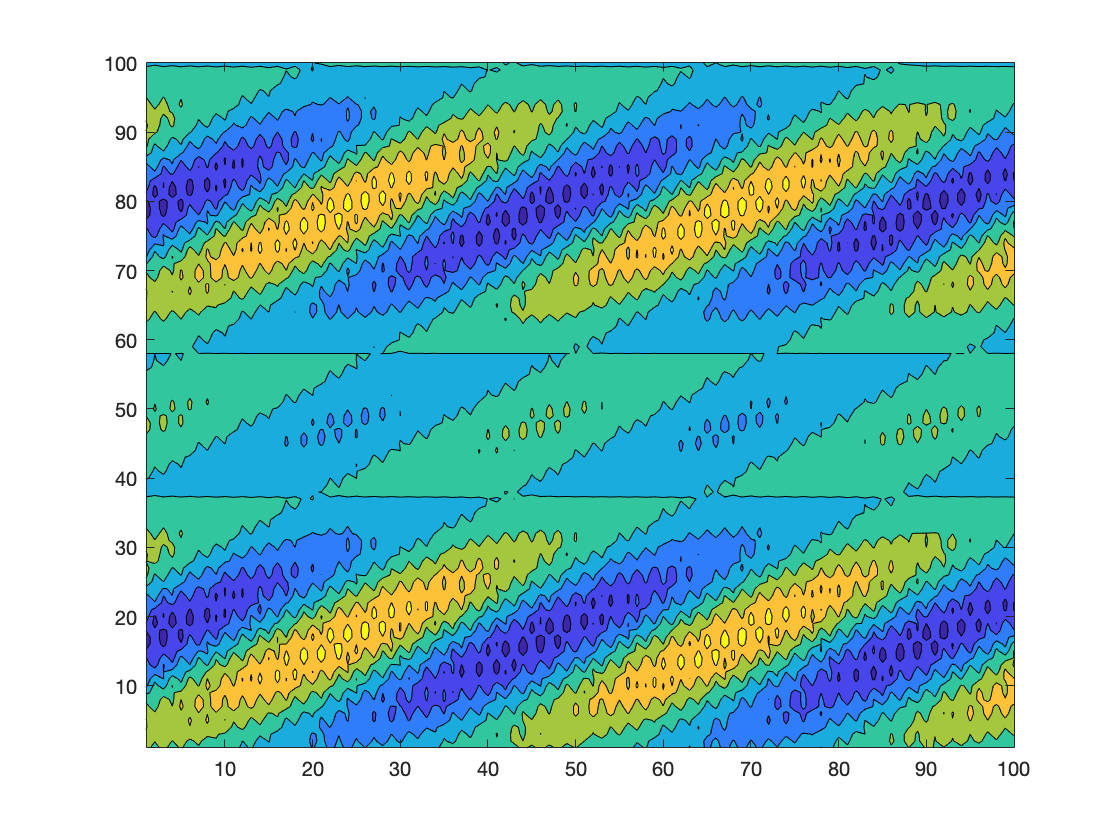

contourf(U)

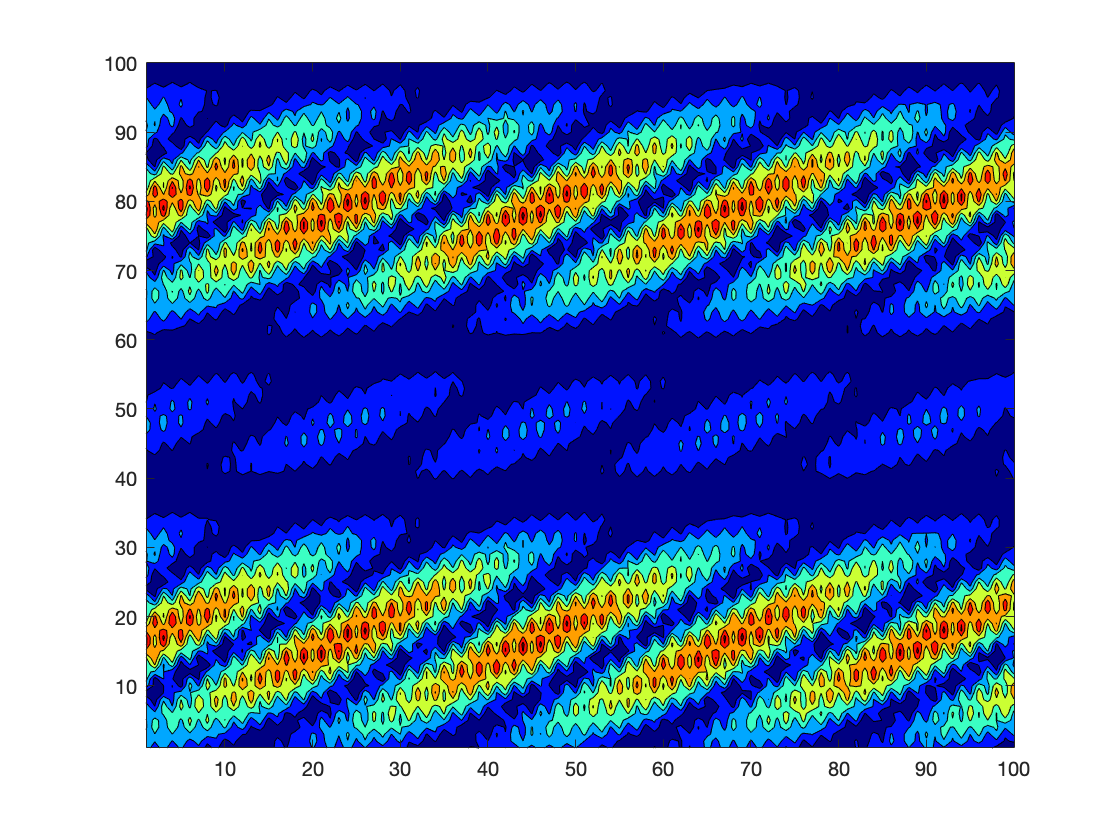

figure
contourf(abs(Vreconst))
shading('interp')
colormap(jet)

function  [Vreconst,deltas,omegas,amplitude,modes] =DMDd_SIADS(d,V,Time,varepsilon1,varepsilon)


%%%%%%%%%%%%%%%%%%%%%%%%%  DMD-d %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% This function solves the HODMD algorithm presented in               %%%
%%% Le Clainche & Vega, SIAM J. on Appl. Dyn. Sys. 16(2):882-925, 2017  %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% %% INPUT: %%
%%% d: parameter of DMD-d (higher order Koopman assumption)
%%% V: snapshot matrix
%%% Time: vector time
%%% varepsilon1: first tolerance (SVD)
%%% varepsilon: second tolerance (DMD-d modes)
%%% %% OUTPUT: %%
%%% Vreconst: reconstruction of the snapshot matrix V
%%% deltas: growht rate of DMD modes
%%% omegas: frequency of DMD modes(angular frequency)
%%% amplitude: amplitude of DMD modes
%%% modes: DMD modes
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


[J,K]=size(V);

% STEP 1: SVD of the original data

[U,Sigma,T]=svd(V,'econ');
sigmas=diag(Sigma);
n=length(sigmas);

NormS=norm(sigmas,2);
kk=0;
for k=1:n
    if norm(sigmas(k:n),2)/NormS>varepsilon1
        kk=kk+1;
    end
end

U=U(:,1:kk);

% Create reduced snapshots matrix
hatT=Sigma(1:kk,1:kk)*T(:,1:kk)';
[N,~]=size(hatT);

% Create the modified snapshot matrix
tildeT=zeros(d*N,K-d+1);
for ppp=1:d
    tildeT((ppp-1)*N+1:ppp*N,:)=hatT(:,ppp:ppp+K-d);
end

% Dimension reduction
[U1,Sigma1,T1]=svd(tildeT,'econ');
sigmas1=diag(Sigma1);

Deltat=Time(2)-Time(1);
n=length(sigmas1);

NormS=norm(sigmas1,2);
kk1=0;
for k=1:n
    RRMSEE(k)=norm(sigmas1(k:n),2)/NormS;
    if RRMSEE(k)>varepsilon1
        kk1=kk1+1;
    end
end


U1=U1(:,1:kk1);
hatT1=Sigma1(1:kk1,1:kk1)*T1(:,1:kk1)';

% Reduced modified snapshot matrix
[~,K1]=size(hatT1);
[tildeU1,tildeSigma,tildeU2]=svd(hatT1(:,1:K1-1),'econ');

% Reduced modified Koopman matrix
tildeR=hatT1(:,2:K1)*tildeU2*inv(tildeSigma)*tildeU1';
[tildeQ,tildeMM]=eig(tildeR);
eigenvalues=diag(tildeMM);

M=length(eigenvalues);
qq=log(eigenvalues);
deltas=real(qq)/Deltat;
omegas=imag(qq)/Deltat;

Q=U1*tildeQ;
Q=Q((d-1)*N+1:d*N,:);
[NN,MMM]=size(Q);

for m=1:MMM
    NormQ=Q(:,m);
    Q(:,m)= Q(:,m)/norm(NormQ(:),2);
end

% Calculate amplitudes
Mm=zeros(NN*K,M);
Bb=zeros(NN*K,1);
aa=eye(MMM);
for k=1:K
    Mm(1+(k-1)*NN:k*NN,:)=Q*aa;
    aa=aa*tildeMM;
    Bb(1+(k-1)*NN:k*NN,1)=hatT(:,k);
end

[Ur,Sigmar,Vr]=svd(Mm,'econ');
a=Vr*(Sigmar\(Ur'*Bb));

u=zeros(NN,M);
for m=1:M
    u(:,m)=a(m)*Q(:,m);
end
amplitude=zeros(M,1);

for m=1:M
    aca=U*u(:,m);
    amplitude(m)=norm(aca(:),2)/sqrt(J);
end

UU=[u;deltas';omegas';amplitude']';
UU1=sortrows(UU,-(NN+3));

UU=UU1';
u=UU(1:NN,:);
deltas=UU(NN+1,:);
omegas=UU(NN+2,:);
amplitude=UU(NN+3,:);
kk3=0;

for m=1:M
    if amplitude(m)/amplitude(1)>varepsilon
        kk3=kk3+1;
    else
    end
end

u=u(:,1:kk3);
deltas=deltas(1:kk3);
omegas=omegas(1:kk3);
amplitude=amplitude(1:kk3);

% Reconstruction of the original snapshot matrix
hatTreconst=zeros(N,K);
for k=1:K
    hatTreconst(:,k)= ContReconst_SIADS(Time(k),Time(1),u,deltas,omegas);
end

Vreconst=U*hatTreconst;

% Calculation of DMD modes
modes=zeros(J,kk3);
amplitude0=zeros(kk3,1);
for m=1:kk3
    NormMode=norm(U*u(:,m),2)/sqrt(J);
    amplitude0(m)=NormMode;
    modes(:,m)=U*u(:,m)/NormMode;
end
end